a = 1 + mod(137,3)

a = 3

%Q1
% Step 1: Read the audio file
audioFilePath = 'violin3.wav';  % Replace with the path to your audio file
[y, fs] = audioread(audioFilePath);

% Step 2: Compute the FFT of the audio signal
N = length(y);  % Length of the audio signal
Y = fft(y);     % Compute the FFT

% Step 3: Find the fundamental frequency
frequencies = (0:N-1)*(fs/N);  % Frequency axis
magnitude = 20*log10(abs(Y));            % Magnitude of FFT
[~, idx] = max(magnitude(1:N/2+1));  % Find the index of the maximum magnitude
fundamentalFrequency = frequencies(idx);  % Fundamental frequency in Hz

% Display the results
fprintf('Fundamental Frequency: %.2f Hz\n', fundamentalFrequency);

Fundamental Frequency: 261.45 Hz


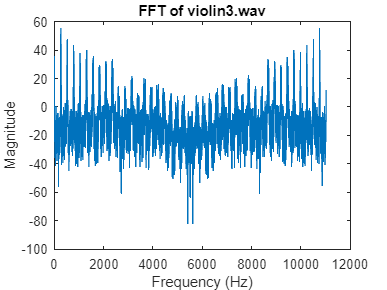

figure;
% You can also plot the FFT if desired
plot(frequencies, magnitude);
title('FFT of violin3.wav');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

%Q2
figure;
% Step 1: Read the audio file
audioFilePath = 'whistle1.mp4';  % Replace with the path to your audio file
[y, fs] = audioread(audioFilePath);

% Step 2: Compute the FFT of the audio signal
N = length(y);  % Length of the audio signal
Y = fft(y);     % Compute the FFT

% Step 3: Find the fundamental frequency
frequencies = (0:N-1)*(fs/N);  % Frequency axis
magnitude = 20*log10(abs(Y));            % Magnitude of FFT
[~, idx] = max(magnitude(1:N/2+1));  % Find the index of the maximum magnitude
fundamentalFrequency = frequencies(idx);  % Fundamental frequency in Hz

% Display the results
fprintf('Fundamental Frequency: %.2f Hz\n', fundamentalFrequency);

Fundamental Frequency: 1464.26 Hz


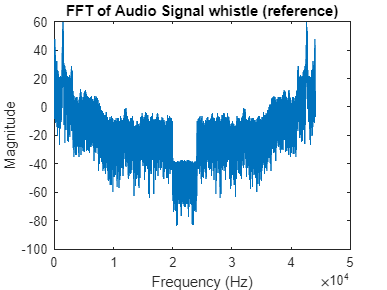

figure;
% You can also plot the FFT if desired
plot(frequencies, magnitude);
title('FFT of Audio Signal whistle (reference)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Step 1: Read the audio file
audioFilePath = 'Test1.mp4';  % Replace with the path to your audio file
[y, fs] = audioread(audioFilePath);

% Step 2: Compute the FFT of the audio signal
N = length(y);  % Length of the audio signal
Y = fft(y);     % Compute the FFT

% Step 3: Find the fundamental frequency
frequencies = (0:N-1)*(fs/N);  % Frequency axis
magnitude = 20*log10(abs(Y));            % Magnitude of FFT
[~, idx] = max(magnitude(1:N/2+1));  % Find the index of the maximum magnitude
fundamentalFrequency1 = frequencies(idx);  % Fundamental frequency in Hz
fprintf('Fundamental Frequency: %.2f Hz\n', fundamentalFrequency1);

Fundamental Frequency: 1397.58 Hz


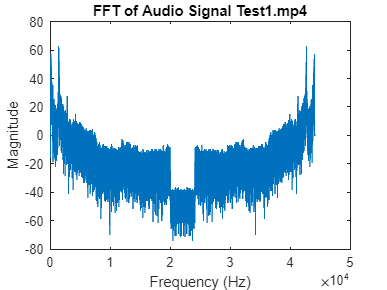

% Display the results
figure;
% You can also plot the FFT if desired
plot(frequencies, magnitude);
title('FFT of Audio Signal Test1.mp4');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

if((fundamentalFrequency1> 1391.047) && (fundamentalFrequency1<1537.473))
    fprintf('ACCESS GRANTED');
else
    fprintf('ACCESS DENIED');
end

ACCESS GRANTED

% Step 1: Read the audio file
audioFilePath = 'test2.mp4';  % Replace with the path to your audio file
[y, fs] = audioread(audioFilePath);

% Step 2: Compute the FFT of the audio signal
N = length(y);  % Length of the audio signal
Y = fft(y);     % Compute the FFT

% Step 3: Find the fundamental frequency
frequencies = (0:N-1)*(fs/N);  % Frequency axis
magnitude = 20*log10(abs(Y));            % Magnitude of FFT
[~, idx] = max(magnitude(1:N/2+1));  % Find the index of the maximum magnitude
fundamentalFrequency2 = frequencies(idx);  % Fundamental frequency in Hz

% Display the results
fprintf('Fundamental Frequency: %.2f Hz\n', fundamentalFrequency2);

Fundamental Frequency: 76.19 Hz


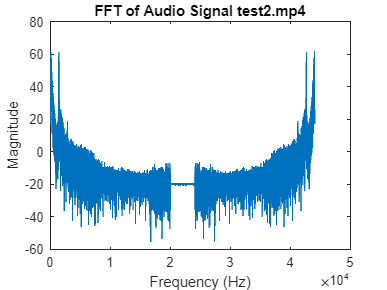

figure;
% You can also plot the FFT if desired
plot(frequencies, magnitude);
title('FFT of Audio Signal test2.mp4');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

if((fundamentalFrequency2> 1391.047) && (fundamentalFrequency2<1537.473))
    fprintf('ACCESS GRANTED');
else
    fprintf('ACCESS DENIED');
end

ACCESS DENIED

% Step 1: Read the audio file
audioFilePath = 'Test3.m4a';  % Replace with the path to your audio file
[y, fs] = audioread(audioFilePath);

% Step 2: Compute the FFT of the audio signal
N = length(y);  % Length of the audio signal
Y = fft(y);     % Compute the FFT

% Step 3: Find the fundamental frequency
frequencies = (0:N-1)*(fs/N);  % Frequency axis
magnitude = 20*log10(abs(Y));            % Magnitude of FFT
[~, idx] = max(magnitude(1:N/2+1));  % Find the index of the maximum magnitude

fundamentalFrequency3 = frequencies(idx);  % Fundamental frequency in Hz

% Display the results
fprintf('Fundamental Frequency: %.2f Hz\n', fundamentalFrequency3);

Fundamental Frequency: 1409.26 Hz


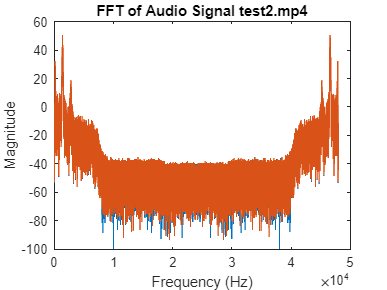

figure;
% You can also plot the FFT if desired
plot(frequencies, magnitude);
title('FFT of Audio Signal test2.mp4');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

if((fundamentalFrequency3> 1391.047) && (fundamentalFrequency3<1537.473))
    fprintf('ACCESS GRANTED');
else
    fprintf('ACCESS DENIED');
end

ACCESS GRANTED

%Q3
% Step 1: Read the audio file
audioFilePath = 'Opera.wav';  % Replace with the path to your audio file
[y, fs] = audioread(audioFilePath);
subplot(2,1,1)
plot(y)
title('Audio Signal Opera.wav');
xlabel('Sample index');
ylabel('Sample Magnitudes');
% Step 2: Compute the FFT of the audio signal
N = length(y);  % Length of the audio signal
Y = fft(y);     % Compute the FFT

% Step 3: Find the fundamental frequency
frequencies = (0:N-1)*(fs/N);  % Frequency axis
magnitude = 20*log10(abs(Y));            % Magnitude of FFT
[~, idx] = max(magnitude(1:N/2+1));  % Find the index of the maximum magnitude
fundamentalFrequency3 = frequencies(idx);  % Fundamental frequency in Hz

% Display the results
fprintf('Fundamental Frequency: %.2f Hz\n', fundamentalFrequency3);

Fundamental Frequency: 622.80 Hz


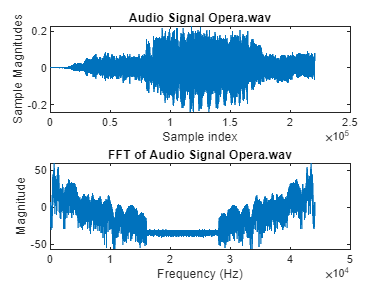


% You can also plot the FFT if desired
subplot(2,1,2)
plot(frequencies, magnitude);
title('FFT of Audio Signal Opera.wav');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

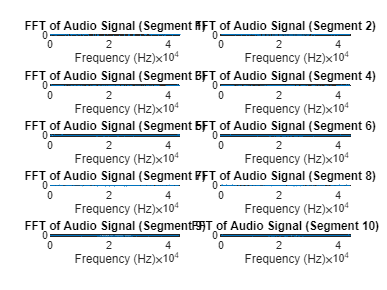

% Step 1: Read the audio file
audioFilePath = 'Opera.wav';  % Replace with the path to your audio file
[y, fs] = audioread(audioFilePath);

% Calculate the total number of figures and samples per figure
numFigures = 10;
samplesPerFigure = 20000;

% Loop to create and display the figures
for i = 1:numFigures
    % Define the start and end samples for the current figure
    startSample = (i - 1) * samplesPerFigure + 1;
    endSample = min(i * samplesPerFigure, length(y));
    
    % Extract the portion of the audio signal for this figure
    audioSegment = y(startSample:endSample);
    
    % Compute the FFT for the current segment
    N = length(audioSegment);  % Length of the segment
    Y = fft(audioSegment);     % Compute the FFT
    
    % Compute the frequencies and magnitude for the FFT
    frequencies = (0:N-1)*(fs/N);  % Frequency axis
    magnitude = 20*log10(abs(Y));            % Magnitude of FFT
    
    % Find the index of the maximum magnitude as the fundamental frequency
    [~, idx] = max(magnitude(1:N/2+1));
    fundamentalFrequency = frequencies(idx);  % Fundamental frequency in Hz
    
    % Create and display the figure
    subplot(5,2,i);
    plot(frequencies, magnitude);
    title(['FFT of Audio Signal (Segment ', num2str(i), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
end

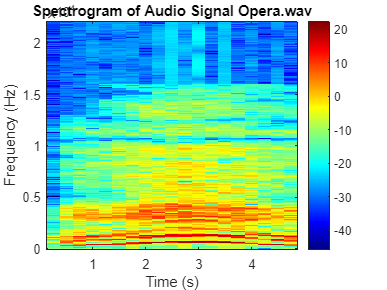

%Spectrogram
figure;
% Step 1: Read the audio file
audioFilePath = 'Opera.wav';  % Replace with the path to your audio file
[y, fs] = audioread(audioFilePath);

% Step 2: Define spectrogram parameters
windowSize = 22000;  % Size of the analysis window (e.g., 256 samples)
overlap = 11000;     % Overlap between consecutive windows (e.g., 50% overlap)
nfft = 512;        % Number of FFT points (higher values give finer frequency resolution)

% Step 3: Compute the spectrogram
[S, F, T] = spectrogram(y, hamming(windowSize), overlap, nfft, fs);

% Step 4: Plot the spectrogram
figure;
imagesc(T, F, 10*log10(abs(S)));  % Convert to dB scale
axis xy;  % Flip the y-axis to have lower frequencies at the bottom
colormap(jet);  % Choose a colormap (optional)
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Audio Signal Opera.wav');
colorbar;  % Display a colorbar showing the magnitude in dB